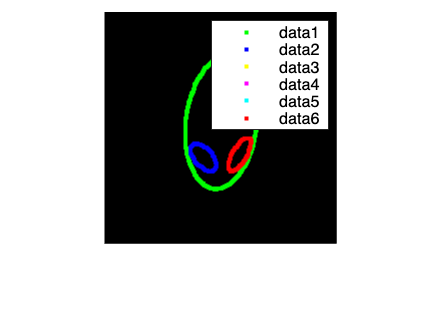

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

% 读取图像
img = edges_laplacian; % 替换为你的图像文件名

gray_img = img;

% 将灰度图像转换为二值图像
bw_img = img;

% 进行形态学操作以去除噪声（可选）
% bw_img = bwareaopen(bw_img, 50);

% 找到所有的连通区域
connected_components = bwconncomp(bw_img);

% 获取每个连通区域的像素索引列表
regions = regionprops(connected_components, 'PixelIdxList');

% 分离出每个连通区域的数据集
num_regions = numel(regions);
figure;
imshow(bw_img); 
hold on;
colors = ['r', 'g', 'b', 'y', 'm', 'c']; % 为每个区域指定不同的颜色
mouth = [];
head = [];
eye1 = [];
for i = 1:num_regions
    % 获取每个区域的像素位置
    [row, col] = ind2sub(size(bw_img), regions(i).PixelIdxList);
    i
    % 绘制边界
    if i >2 && i < 6
        mouth = [mouth;[row,col]];
    end
    if i == 1
        head = [row,col];
    end
    if i == 6
        eye1 = [row,col];
    end
    if i == 2
        eye2 = [row,col];
    end
    % fit_outer_ellipse(row,col)
    plot(col, row, '.', 'Color', colors(mod(i, length(colors))+1));
    legend()
end

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    3.675663e+03     0.000e+00     1.000e+00     0.000e+00     1.414e+02  
非线性约束函数返回了 Inf；正在尝试一个新点...
    1          13    3.308097e+02     2.433e+00     7.000e-01     3.638e+01     3.835e+01  
    2          19    5.930429e+02     8.567e-01     1.000e+00     5.286e+00     3.312e+01  
    3          25    8.705794e+02     2.170e-01     1.000e+00     4.421e+00     1.453e+01  
    4          31    1.009859e+03     2.388e-02     1.000e+00     1.953e+00     4.665e+00  
    5          37    1.029038e+03     3.601e-04     1.000e+00     2.590e-01     3.675e-01  
    6          43    1.029320e+03     8.145e-08     1.000e+00     3.826e-03     6.478e-03  
    7          49    1.029321e+03     3.331e-15     1.000e+00     8.247e-07     1.031e-05  



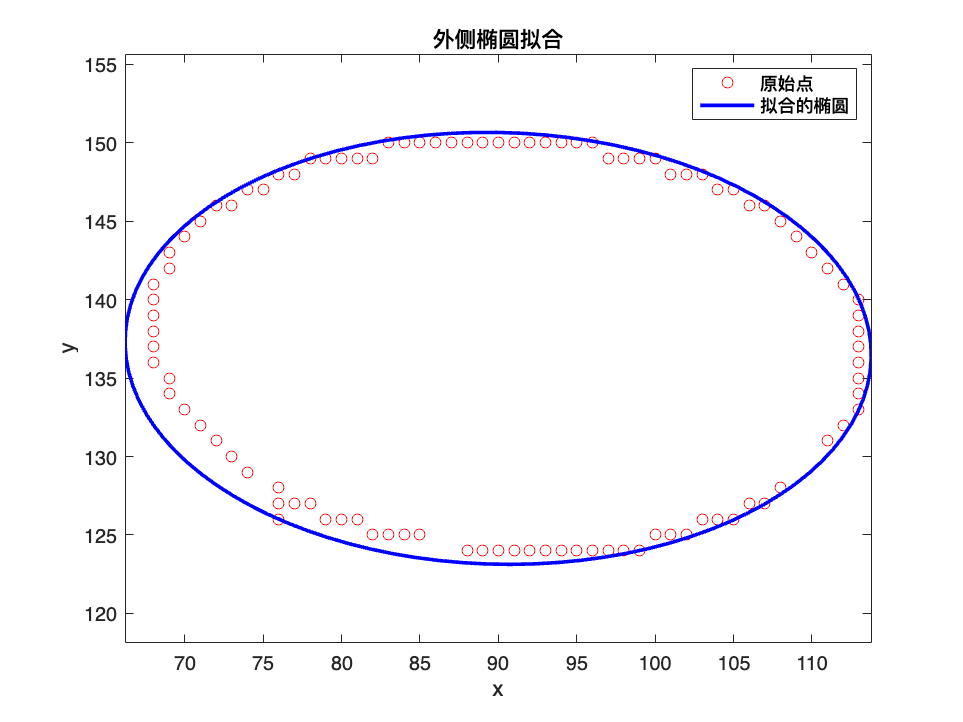

fit_outer_ellipse(mouth(:,1),mouth(:,2))

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    3.719646e+04     0.000e+00     1.000e+00     0.000e+00     4.650e+02  
非线性约束函数返回了 Inf；正在尝试一个新点...
    1          13    3.347681e+03     2.239e+00     7.000e-01     1.178e+02     1.300e+02  
    2          19    5.822368e+03     7.638e-01     1.000e+00     1.602e+01     1.800e+02  
    3          25    8.203420e+03     1.778e-01     1.000e+00     1.246e+01     2.713e+02  
    4          31    9.231208e+03     1.578e-02     1.000e+00     4.971e+00     1.894e+02  
    5          37    9.344334e+03     1.850e-04     1.000e+00     5.789e-01     9.327e-01  
    6          43    9.345488e+03     2.667e-08     1.000e+00     6.891e-03     1.187e-01  
    7          49    9.345488e+03     4.441e-16     1.000e+00     9.610e-07     2.028e-04  



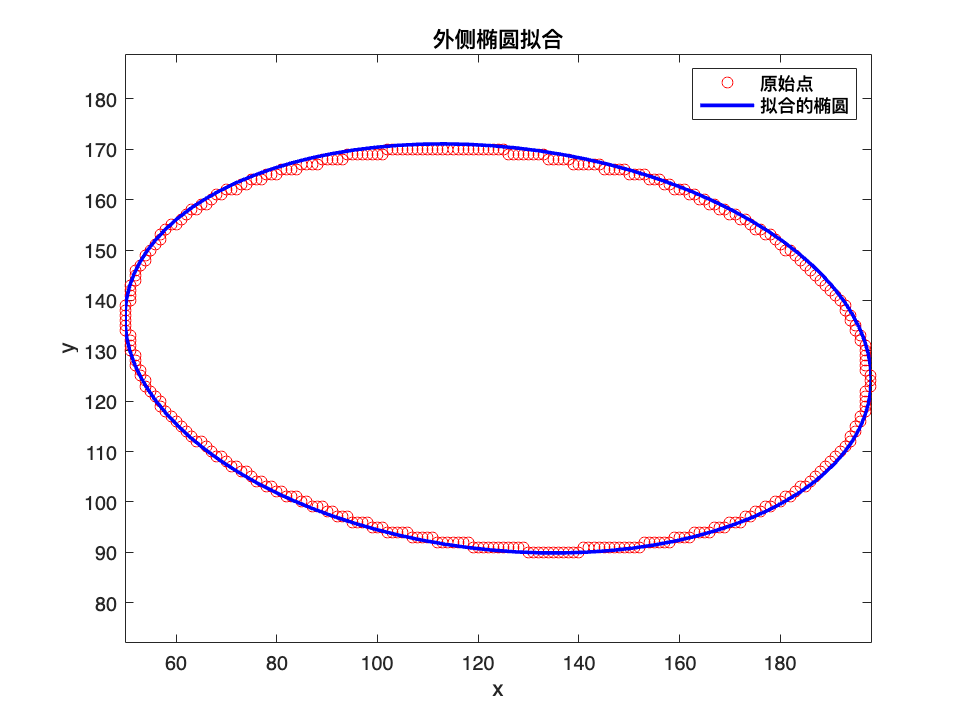

fit_outer_ellipse(head(:,1),head(:,2))

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    3.022212e+03     0.000e+00     1.000e+00     0.000e+00     1.162e+02  
非线性约束函数返回了 Inf；正在尝试一个新点...
    1          13    2.719991e+02     2.817e+00     7.000e-01     3.166e+01     2.826e+01  
    2          19    3.961872e+02     1.000e+00     1.000e+00     4.029e+00     3.520e+01  
    3          25    4.984588e+02     2.897e-01     1.000e+00     3.818e+00     2.616e+01  
    4          31    5.563136e+02     4.111e-02     1.000e+00     2.215e+00     3.293e+01  
    5          37    5.688021e+02     1.453e-03     1.000e+00     4.748e-01     1.061e+01  
    6          43    5.692418e+02     1.709e-06     1.000e+00     1.674e-02     1.613e-01  
    7          49    5.692423e+02     2.375e-12     1.000e+00     1.952e-05     5.970e-05  



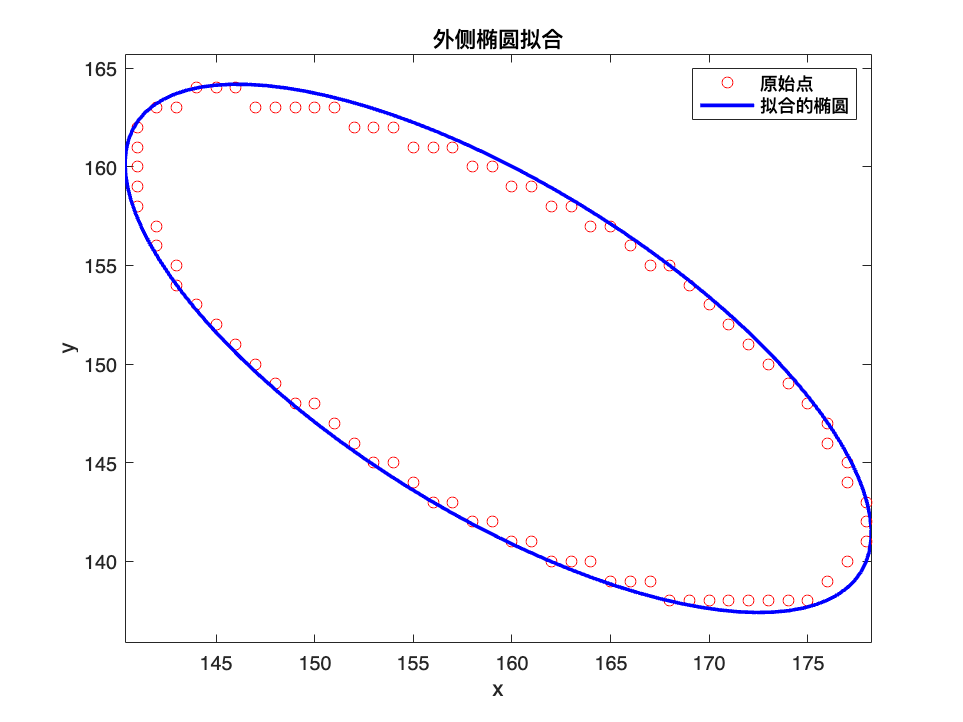

fit_outer_ellipse(eye1(:,1),eye1(:,2))%右下

fit_outer_ellipse(eye2(:,1),eye2(:,2))%左下

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    2.824292e+03     0.000e+00     1.000e+00     0.000e+00     9.739e+01  
非线性约束函数返回了 Inf；正在尝试一个新点...
    1          13    2.541863e+02     3.595e+00     7.000e-01     2.979e+01     5.705e+01  
    2          20    3.451898e+02     2.245e+00     7.000e-01     2.547e+00     1.109e+01  
    3          28    4.004429e+02     1.574e+00     4.900e-01     1.473e+00     7.220e+00  
    4          34    4.872034e+02     5.070e-01     1.000e+00     3.866e+00     1.014e+02  
    5          40    5.853581e+02     1.077e-01     1.000e+00     2.641e+00     9.862e+01  
    6          46    6.154368e+02     6.489e-03     1.000e+00     9.159e-01     2.636e+01  
    7          52    6.179459e+02     4.286e-05     1.000e+00     7.741e-02     1.162e+00  
    8          58    6.179616e+02     1.535e-09     1.0

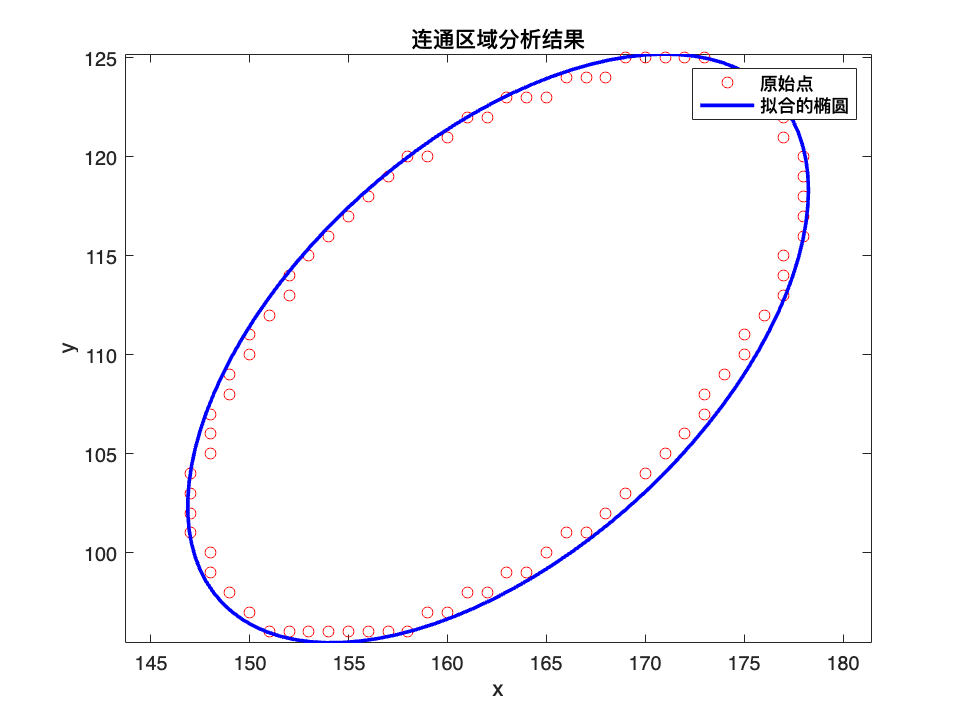

hold off;
title('连通区域分析结果');